# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

MAT292, Fall 2018, Stinchcombe & Khovanskii, modified from MAT292, Fall 2017, Stinchcombe & Sinnamon, modified from MAT292, Fall 2015, Sousa, modified from MAT292, Fall 2013, Sinnamon & Sousa, modified from MAT292, Fall 2011, Hart & Pym

## Student Information

Student Name: Ruchir Tullu

Student Number: 1004220951

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation. Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

f1 = @(t,y) y*tan(t) + sin(t);

%Parameters
t0 = 0;     
t1 = pi;
y0 = -1/2;

soln1 = ode45( f1, [t0,t1], y0);

%Exact solution plotting values
xx = linspace(0, pi, 100);
yy = (1/2).*(tan(xx).*sin(xx) - (1./(cos(xx))));        % Exact solution

% Exact solution;
% y = (1/2)* (tan(t)sin(t) - (1/cos(t)))

plot(xx, yy, 'x', 'color', 'r', 'Linestyle', '--');
title('Exercise 2(a)');
xlabel('t');
ylabel('y');
hold on

N1 = 313;
h1 = (pi-0)/N1;
[IEMt1, IEMy1] = IEM(f1, 0, pi, -1/2, h1);
IEMt1

IEMt1 =          0    0.0100    0.0201    0.0301    0.0401    0.0502    0.0602    0.0703    0.0803    0.0903    0.1004    0.1104    0.1204    0.1305    0.1405    0.1506    0.1606    0.1706    0.1807    0.1907    0.2007    0.2108    0.2208    0.2309    0.2409    0.2509    0.2610    0.2710    0.2810    0.2911    0.3011    0.3111    0.3212    0.3312    0.3413    0.3513    0.3613    0.3714    0.3814    0.3914    0.4015    0.4115    0.4216    0.4316    0.4416    0.4517    0.4617    0.4717    0.4818    0.4918


IEMy1

IEMy1 =    -0.5000   -0.5000   -0.4999   -0.4998   -0.4996   -0.4994   -0.4991   -0.4988   -0.4984   -0.4980   -0.4975   -0.4970   -0.4964   -0.4957   -0.4951   -0.4943   -0.4936   -0.4927   -0.4919   -0.4909   -0.4900   -0.4889   -0.4879   -0.4867   -0.4856   -0.4843   -0.4831   -0.4818   -0.4804   -0.4790   -0.4775   -0.4760   -0.4744   -0.4728   -0.4712   -0.4695   -0.4677   -0.4659   -0.4641   -0.4622   -0.4602   -0.4583   -0.4562   -0.4542   -0.4520   -0.4499   -0.4476   -0.4454   -0.4431   -0.4407


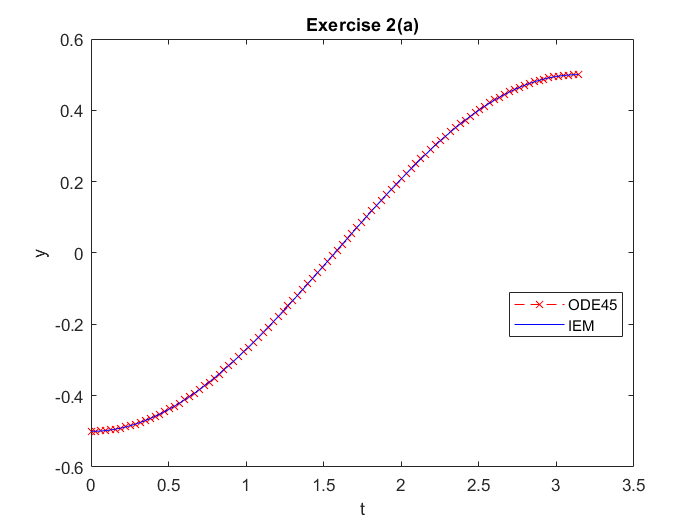

plot(IEMt1, IEMy1, 'Color', 'b')
legend('ODE45', 'IEM', 'Location', 'Best');

hold off

For (a), the IEM solver closely matches the solution given by ode45 for a particular step size given as above, for N=313. Any deviation from this value of N results in a large spike at t = pi/2, as at that point tan(pi/2) tends to infinity. We can notice that ode45 chooses a step size to avoid this problem in this case. through experimentation, values of N ranging from 100-400 and 500-2000 seemed to give a smaller spike at t=pi/2 (ignoring the ideal case of N=313).

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

f2 = @(y,t) 1/(y.^2);

%Parameters
t0 = 1;
t1 = 10;
y0 = 1;

%ODE45 solution:
soln4 = ode45(f2, [t0, t1], y0);

%Plot:
plot(soln4.x, soln4.y, 'color', 'r','Linestyle', '--');
title('Exercise 2(b)');
xlabel('t');
ylabel('y');
hold on

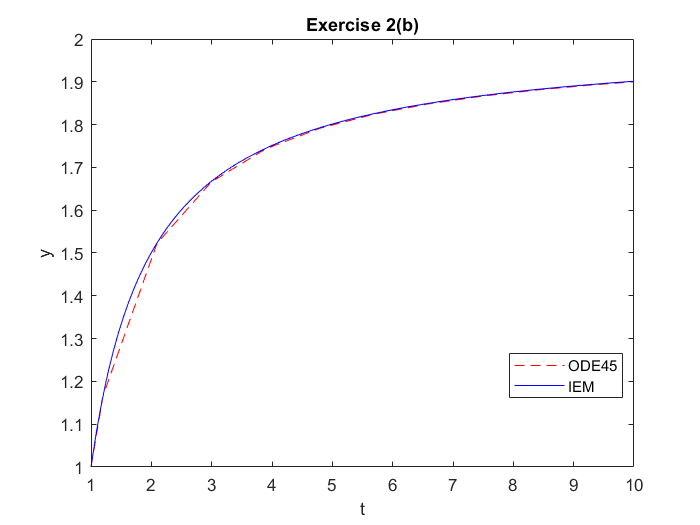

N2 = 100;
h2 = (10-1)/N2;
[IEMt2, IEMy2] = IEM(f2, 1, 10, 1, h2);
plot(IEMt2, IEMy2, 'Color', 'b')
legend('ODE45', 'IEM', 'Location', 'Best');

hold off

We can see that even for a small value of N, IEM approximates the function smoother than ODE45. However, recalling our analysis of error from lab 2, we know that both solutions have a large margin of error as t increases. Both approximated solutions are very similar however.

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

f3 = @(t,y) 1 - t*y/2 ; 

%Parameters:
t0 = 0;
t1 = 10;
y0 = -1;

%solution: 
soln  = ode45(f3, [t0, t1], y0);

plot(soln.x, soln.y, 'r', 'Linestyle', '--');
title('Exercise 2(c)');
xlabel('t');
ylabel('y');
hold on

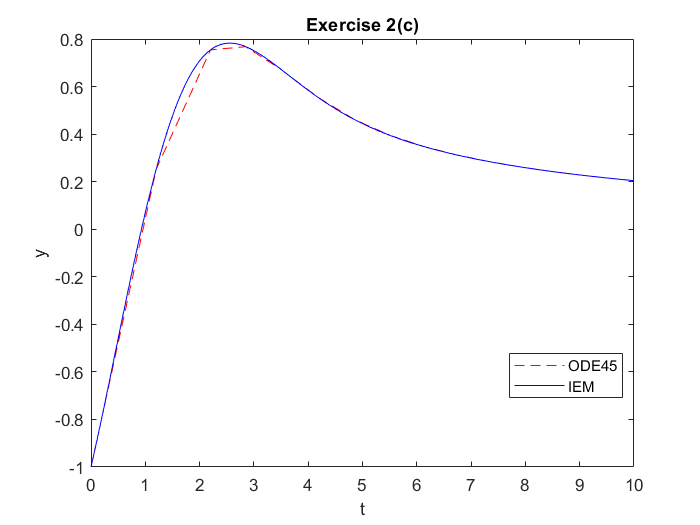

N3 = 500;
h3 = (10-0)/N3;
[IEMt3, IEMy3] = IEM(f3, 0, 10, -1, h3);
plot(IEMt3, IEMy3, 'Color', 'b')
legend('ODE45', 'IEM', 'Location', 'Best');

hold off

The solutions are close to one another, with the smaller step size being taken for IEM resulting in a smoother curve. Because of this there is a slight deviation in the regions t=1 to t=3. 

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`


f4 = @(t,y) y.^3 - t.^2;

%Parameters:
y0 = 1;
t0 = 0;
t1 = 1;

%Solution:
soln = ode45(f4, [t0,t1], y0);

plot(soln.x, soln.y, 'b', 'LineStyle', '--');
title('Exercise 2(d)');
xlabel('t');
ylabel('y');
hold on

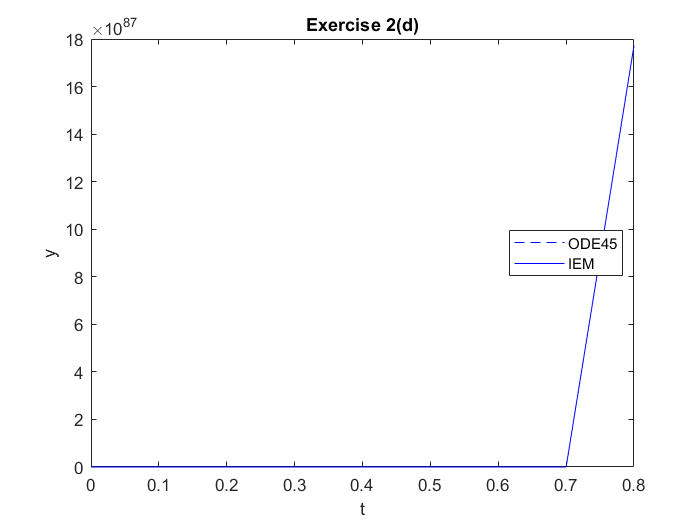

N4 = 10;
h4 = (1-0)/N4;
[IEMt4, IEMy4] = IEM(f4, 0, 10, 1, h4);
plot(IEMt4, IEMy4, 'Color', 'b')
legend('ODE45', 'IEM', 'Location', 'Best');

hold off

As was seen in the previous lab, the error increases exponentially and hence the solution exceedes error tolerances. The solutions do not reach t=1 because of the asymptotal behaviour of the solution curves near t=1 as seen in lab 2.

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method

%(a)
tc=euler(inline('2*t*sqrt( 1 - y^2 )','t','y'), 0, 0: 0.01: 0.5)     %from euler.m

tc =          0         0    0.0002    0.0006    0.0012    0.0020    0.0030    0.0042    0.0056    0.0072    0.0090    0.0110    0.0132    0.0156    0.0182    0.0210    0.0240    0.0272    0.0306    0.0342    0.0380    0.0420    0.0462    0.0506    0.0552    0.0600    0.0650    0.0701    0.0755    0.0811    0.0869    0.0929    0.0990    0.1054    0.1120    0.1187    0.1257    0.1328    0.1402    0.1477    0.1554    0.1633    0.1714    0.1797    0.1881    0.1968    0.2056    0.2146    0.2238    0.2331


tc(end)     % This is y(t=0.5) = 0.2427 using euler.m

ans = 0.2427


%(b)
% We get the analytic solution to be : y = sin(t^2). Evaluating at t = 0.5:
soln4 = sin(0.5^2)      % = 0.2474

soln4 = 0.2474


%(c)
%Using the definition that E_n <= ((1+M)/2) * delta_t * (exp(M*0.5) - 1)
%Where M is the maximum bound of dy/dt = f, ∂f/∂t, and ∂f/∂y, delta_t is the time step, and n is the number of terms.
% We find that the above derivates are bounded by values of 1, -1, and 2 respectively. So here we choose M=2.
% We use delta_t to be 0.01 and n to be 51. Using these values we obtain E_n = 0.026. 

%(d)
% The absolute error is |0.2427-0.2474| = 0.0047. We see that the local error at t = 0.5 is less than the global error.
%This is as expected; the global error provides an upper bound to the local error at any point.

%(e)
tc=euler(inline('2*t*sqrt( 1 - y^2 )','t','y'), 0, 0: 0.001: 0.5)     %delta_t = 0.001

tc =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024


tc(end)     % This is y(t=0.5) = 0.2469

ans = 0.2469


% Error is then |0.2474 - 0.2469| = 0.0005. This is less than the global error.
% We observe that the error reduces with a smaller step size. The error decreases linearly with the step size, 
% thus cinfirming Euler's method as being a linear (order 1 ) approximation.


## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

This formula is trying to reduce the step size for each error that exceeds the tolerance. This way, we recursively reduce the error below the tolerance. Specifically, it is choosing the maximum of `(tol/abs(D),0.3), then choosing a minimum value between the aforementioned maximum and 2 (M). Then we multiply by 0.9*h, where h is the step size. Essentially the minimum will always be one of the terms inside the max(), because multiplying by 2*h*0.9 would result in a larger step size than before. The 0.9 is most likely meant to ensure that the step size is a fraction of its original value regardless of what the final produce of the min(max()) will be. `The 0.9 is a safety factor to ensure success on the next try. The minimum and maximum are to prevent extreme changes from the previous stepsize.

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

ex5 = euler(inline('2*t*sqrt( 1 - y^2 )','t','y'), 0, 0: 0.025: 0.75)     %from euler.m

ex5 =          0         0    0.0013    0.0037    0.0075    0.0125    0.0187    0.0262    0.0350    0.0450    0.0562    0.0687    0.0824    0.0974    0.1135    0.1309    0.1495    0.1693    0.1902    0.2123    0.2355    0.2598    0.2852    0.3115    0.3389    0.3671    0.3962    0.4260    0.4565    0.4877    0.5193


(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

f_A = @(t,y) 2*t*sqrt( 1 - y^2 );
h_A = 0.025;
[AEMt, AEMy] = adaptive_euler1(f_A, 0, 0.75, 0, h_A)

AEMt =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1750    0.2000    0.2250    0.2500    0.2750    0.3000    0.3250    0.3500    0.3750    0.4000    0.4250    0.4500    0.4750    0.5000    0.5250    0.5500    0.5750    0.6000    0.6250    0.6500    0.6750    0.7000    0.7250    0.7500


AEMy =          0         0    0.0013    0.0037    0.0075    0.0125    0.0187    0.0262    0.0350    0.0450    0.0562    0.0687    0.0824    0.0974    0.1135    0.1309    0.1495    0.1693    0.1902    0.2123    0.2355    0.2598    0.2852    0.3115    0.3389    0.3671    0.3962    0.4260    0.4565    0.4877    0.5193


(c) Plot both approximations together with the exact solution.

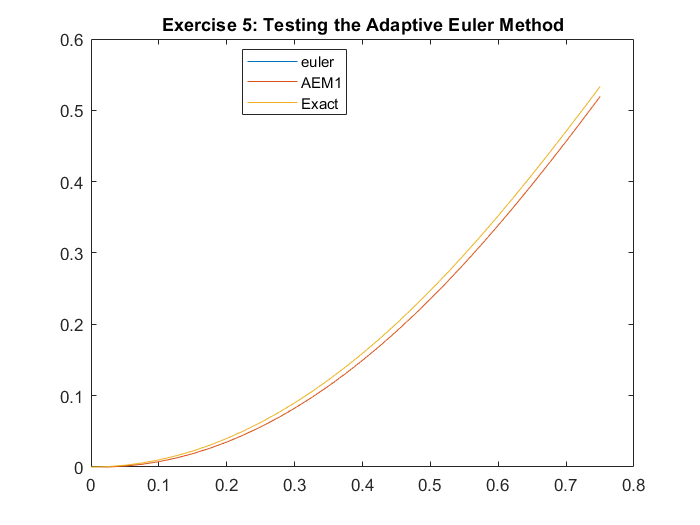

t = linspace(0, 0.75, 31);
plot(t, ex5);
hold on
plot(AEMt, AEMy);
hold on
plot(t, sin(t.^2))
hold off
title("Exercise 5: Testing the Adaptive Euler Method")
legend('euler','AEM1','Exact', 'Location', 'best')


% We see that the Euler method matches the AEM, but both deviate from the exact solution.

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

In theory, the adaptive stepsize method should yield the better (more accurate) result. However, they seem to show more or less the same result. This may be due to the small step size used.

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

tc=euler(inline('2*t*sqrt( 1 - y^2 )','t','y'), 0, 0: 0.01: 1.5)     %from euler.m

tc =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0002 + 0.0000i   0.0006 + 0.0000i   0.0012 + 0.0000i   0.0020 + 0.0000i   0.0030 + 0.0000i   0.0042 + 0.0000i   0.0056 + 0.0000i   0.0072 + 0.0000i   0.0090 + 0.0000i   0.0110 + 0.0000i   0.0132 + 0.0000i   0.0156 + 0.0000i   0.0182 + 0.0000i   0.0210 + 0.0000i   0.0240 + 0.0000i   0.0272 + 0.0000i   0.0306 + 0.0000i   0.0342 + 0.0000i   0.0380 + 0.0000i   0.0420 + 0.0000i   0.0462 + 0.0000i   0.0506 + 0.0000i   0.0552 + 0.0000i   0.0600 + 0.0000i   0.0650 + 0.0000i   0.0701 + 0.0000i   0.0755 + 0.0000i   0.0811 + 0.0000i   0.0869 + 0.0000i   0.0929 + 0.0000i   0.0990 + 0.0000i   0.1054 + 0.0000i   0.1120 + 0.0000i   0.1187 + 0.0000i   0.1257 + 0.0000i   0.1328 + 0.0000i   0.1402 + 0.0000i   0.1477 + 0.0000i   0.1554 + 0.0000i   0.1633 + 0.0000i   0.1714 + 0.0000i   0.1797 + 0.0000i   0.1881 + 0.0000i   0.1968 + 0.0000i   0.2056 + 0.0000i   0.2146 + 0.0000i   0.2238 + 0.0000i   0.2331 + 0.0000i


tc(end)     % This is y(t=0.5) = 0.2427 using euler.m

ans = 1.0096 - 0.0018i

tc6 = linspace(0, 1.5, 151);
[AEM6t, AEM6y] = adaptive_euler1(f_A, 0, 1.5, 0, 0.025);
%(b)
t6 = linspace(0, 1.5);

plot( t6 , sin((t6).^2), tc6, tc, AEM6t, AEM6y);

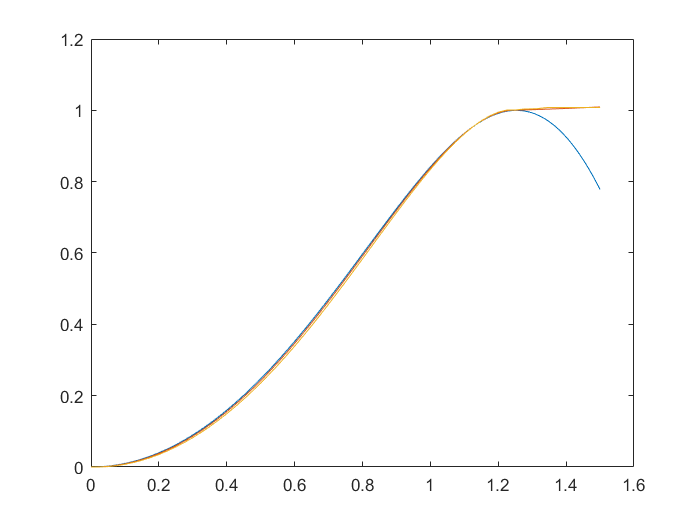

hold on

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

The Euler method fails after y reaches 1 because the values computed become complex-valued. The method is not able to handle these values correctly, and hence the method diverges from the real solution. The approximations become different from the real solution because they way the methods handle the square root: sqrt(1-y^2) after y =1.